# Load Massive Data File

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\');
latestSweep = latestTimeParse(inputPath,'megaSweep');
tic
%Takes about 2 minutes
load(latestSweep)
toc

Elapsed time is 261.227680 seconds.


clear inputPath latestSweep

# Plot some stuff

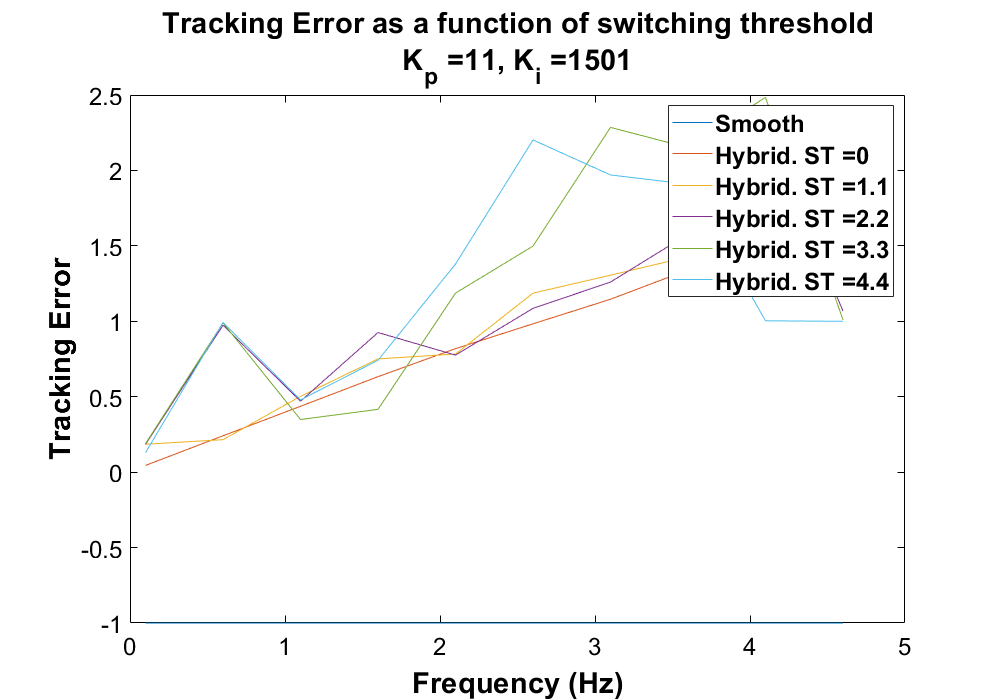

easyPlotter('increasingSwitchThresh','Kp',10,'Ki',1500,sweepData,Kp,Ki,switchThresh,...
    sinfreqsDecimate,pureSinTime,5)

# Plot some other stuff

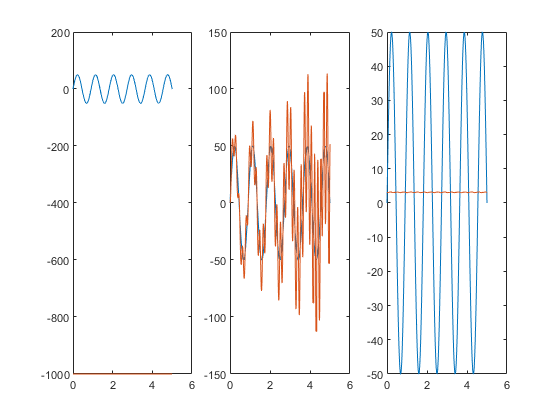

kpIndex = 19

kiIndex = 17

stIndex = 27

fIndex = 3

[kpIndex,kiIndex,stIndex,fIndex] = responsePlot(Kp,Ki,switchThresh,...
    sinfreqsDecimate,181,1601,2.6,1.3,pureSinTime,sweepData)

sweepData(kpIndex,kiIndex,fIndex)

ans = struct with fields:
            Kp: 181
            Ki: 1601
     inputFreq: 1.1000
     smoothOut: [1×1001 double]
         sGain: -1
        sPhase: -1
        sError: -1
    hybridInfo: [1×51 struct]


sweepData(kpIndex,kiIndex,fIndex).hybridInfo(stIndex)

ans = struct with fields:
    switchThresh: 2.6000
       hybridOut: [1×1001 double]
            hFit: [1×1001 double]
           hGain: 0.0073
          hPhase: -0.0058
          hError: 0.9927
         rsquare: -9.7180e-05


# Bad Fits List

r2thresh = 0.5;
badFitList = badFitList(sweepData,r2thresh);

# Animate Hybrid Response

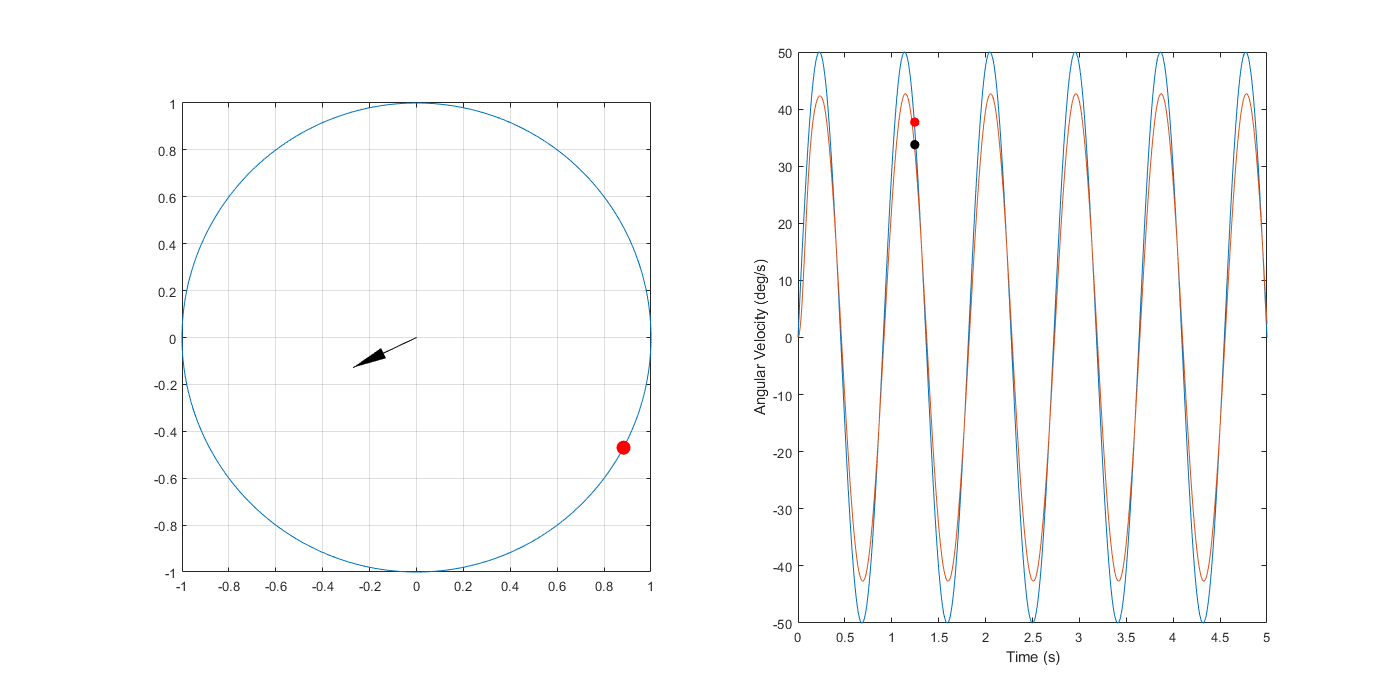

basepath = strcat(commonPath,'\HybridAnimation');
savePath = genFileName(basepath,'HybridAnimation');
savePath = strrep(savePath,'.mat','.avi');
hybridOut = sweepData(kpIndex,kiIndex,fIndex).hybridInfo(stIndex).hybridOut;
smoothOut = sweepData(kpIndex,kiIndex,fIndex).smoothOut;
sinin = 50*sin(2*pi*sinfreqsDecimate(fIndex).*pureSinTime);
AnimationPlotter(sinin,smoothOut,pureSinTime,savePath)

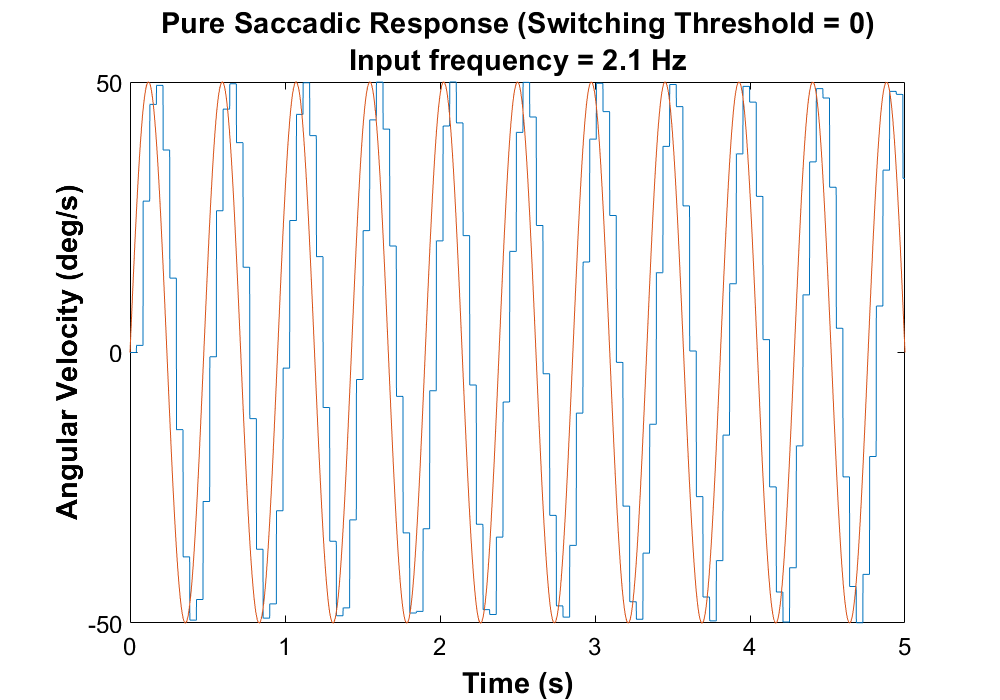




figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,1,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Pure Saccadic Response (Switching Threshold = 0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

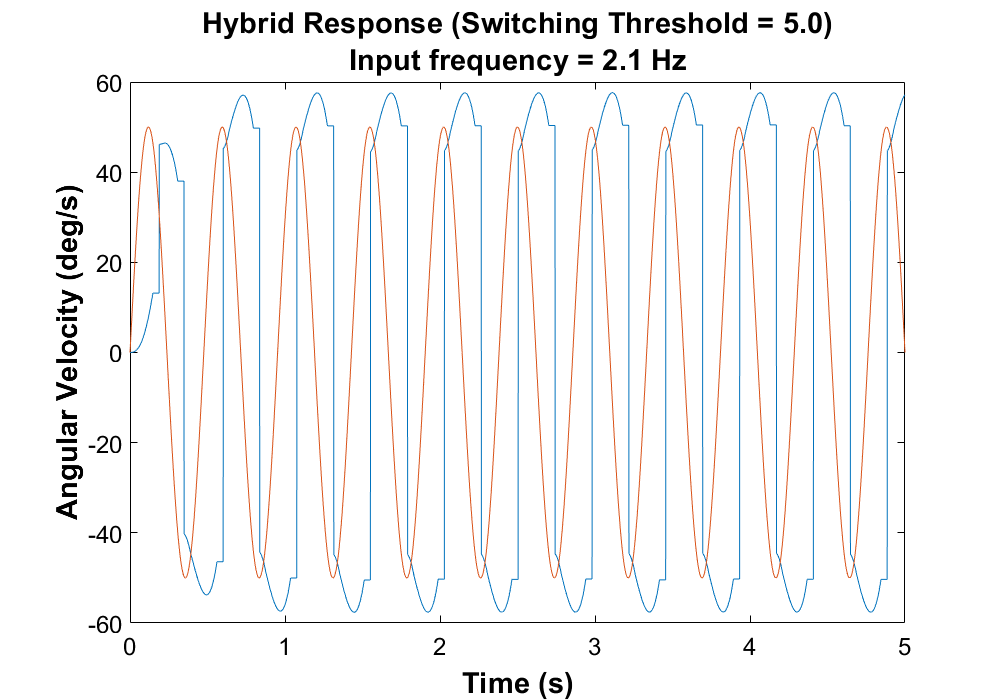


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,11,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response (Switching Threshold = 5.0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

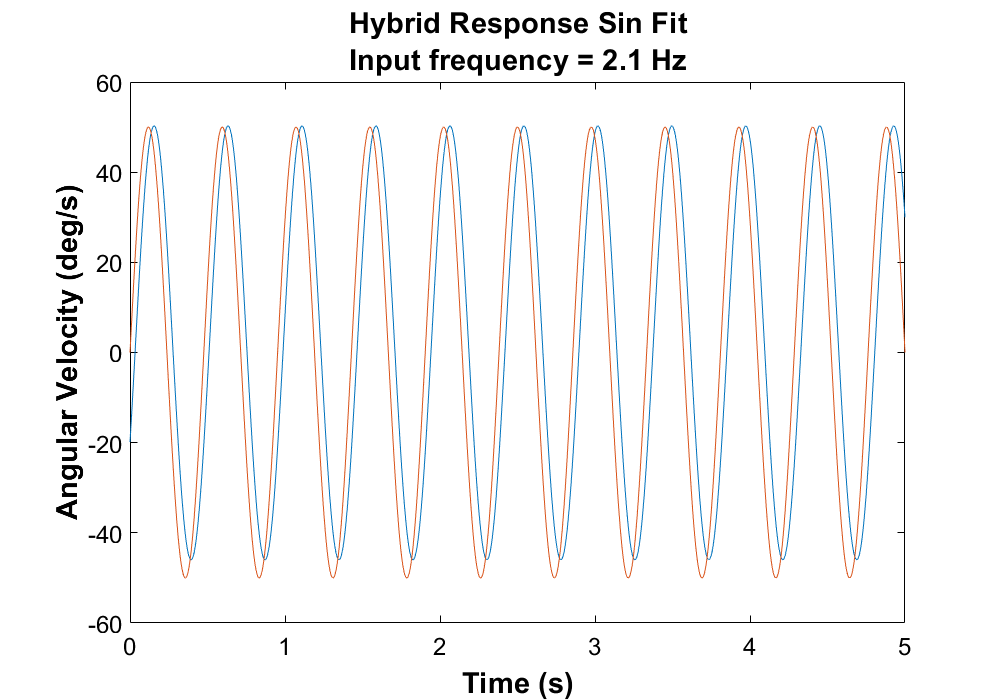


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(5,5,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hFit,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response Sin Fit','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

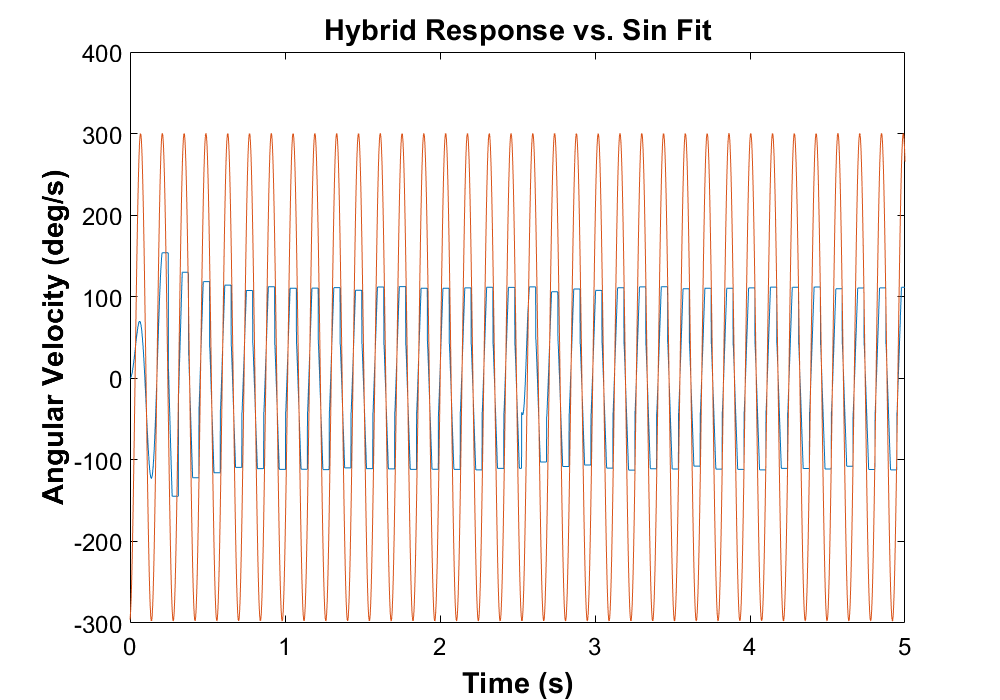


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(9,2,10,15);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,chosenPoint.hFit)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response vs. Sin Fit'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

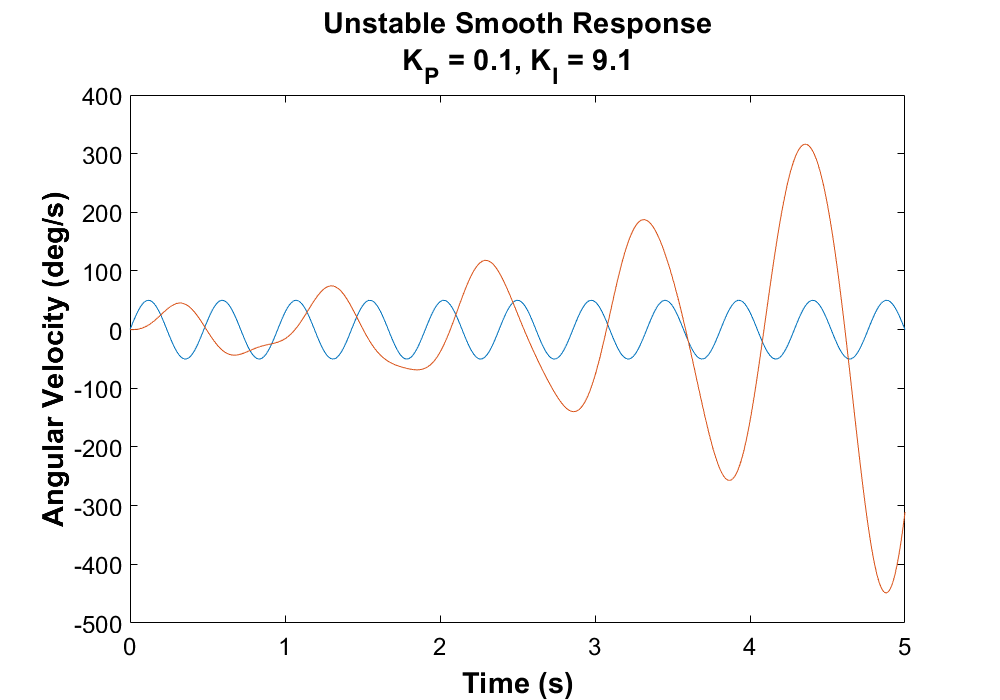



chosenPoint = sweepData(1,10,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
C_tf = tf([0.1 9.1],[1 0]);

%Delay (Pade approximation)
td =.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
den = (1 + num*d_tf);
cl_tf = num/den;

unstable = lsim(cl_tf,sinin,pureSinTime);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(pureSinTime,sinin,pureSinTime,unstable)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Unstable Smooth Response','K_P = 0.1, K_I = 9.1'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')